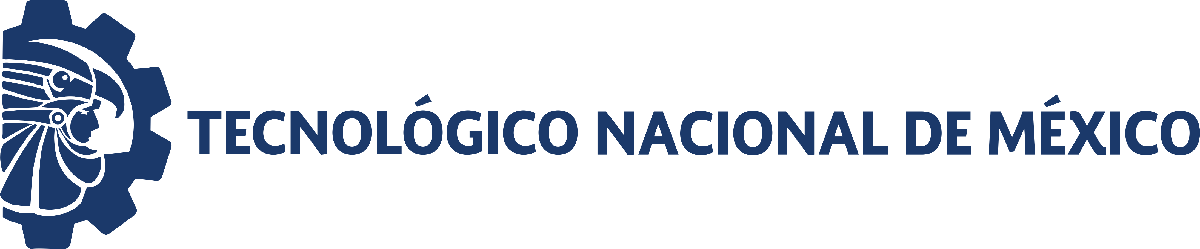                                 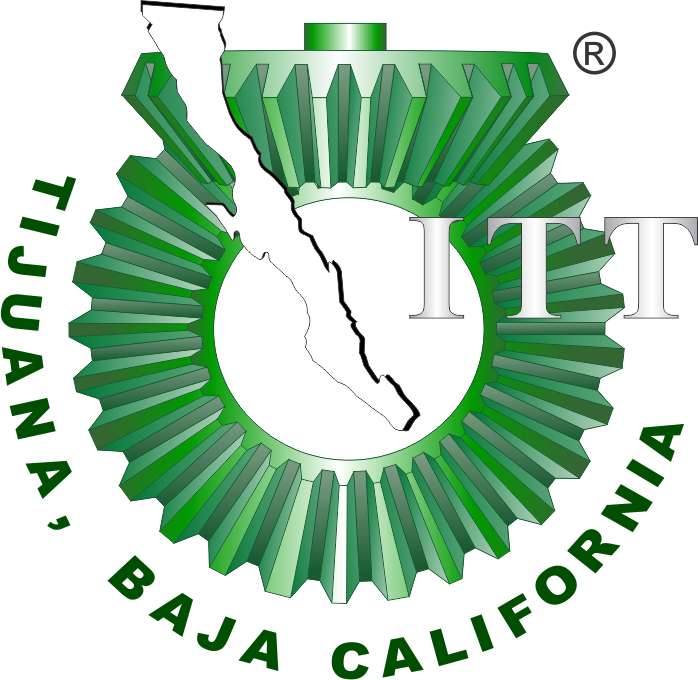

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

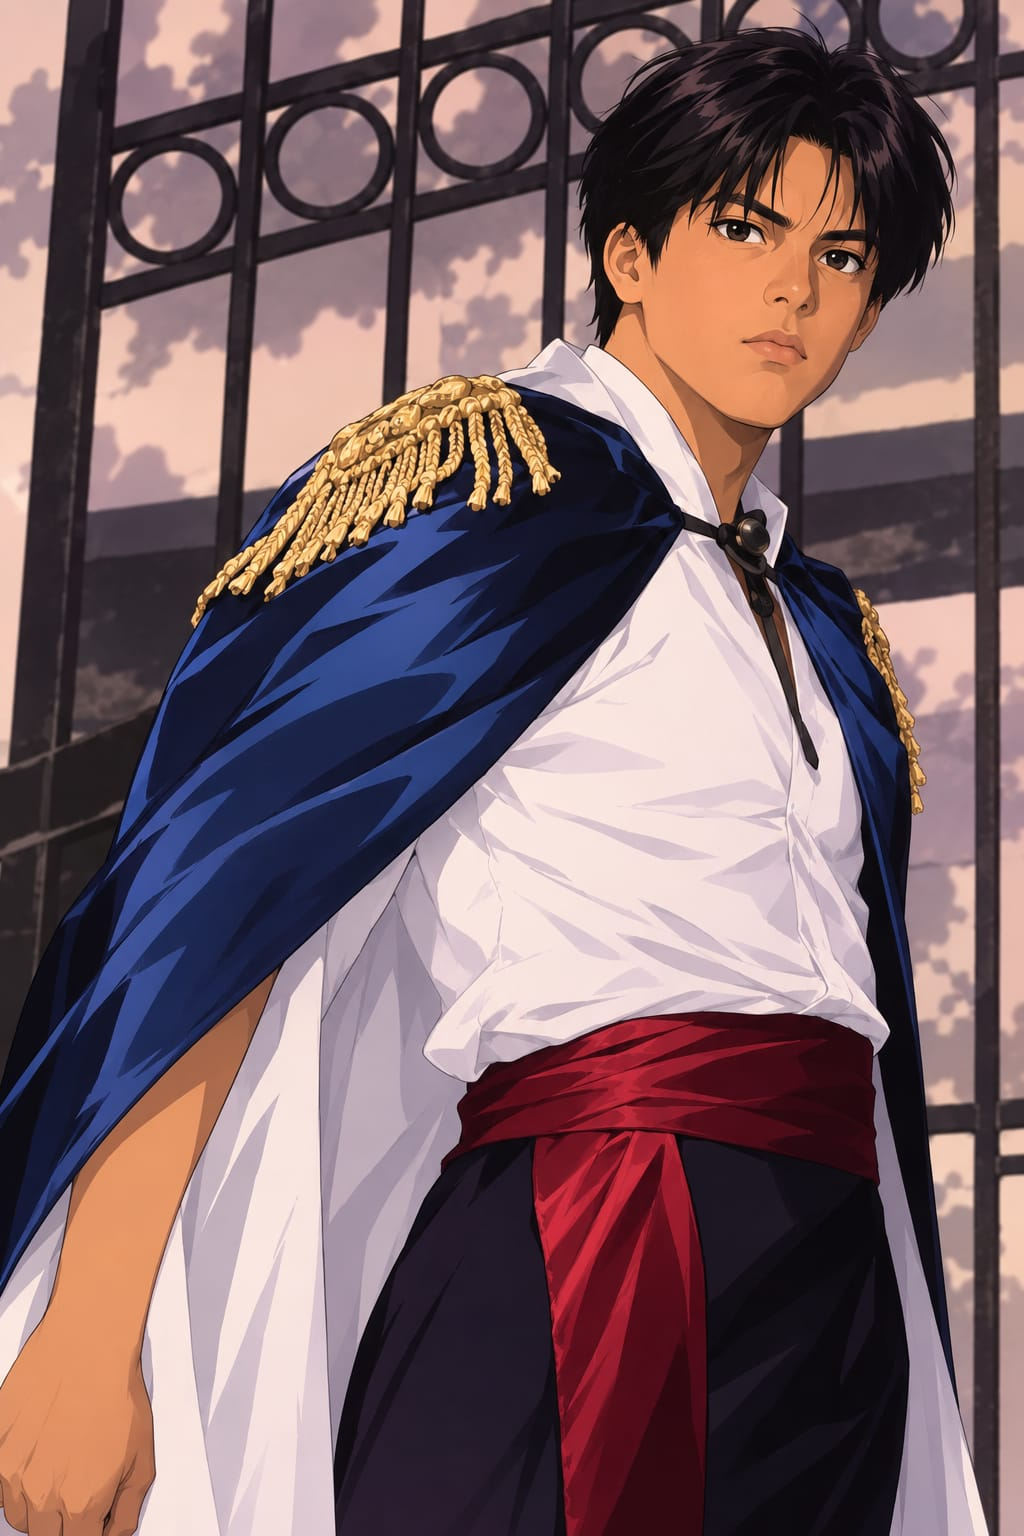

Nombre del alumno: **Emmanuel Cid Pacheco**

Número de control: **23212187**

Correo institucional: **l23212187@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistemas')
parameters.stopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
% set_param('Sistema/PA(t): CE/PA','VectorFotmat','1-0 array');

## Respuesta al escalón

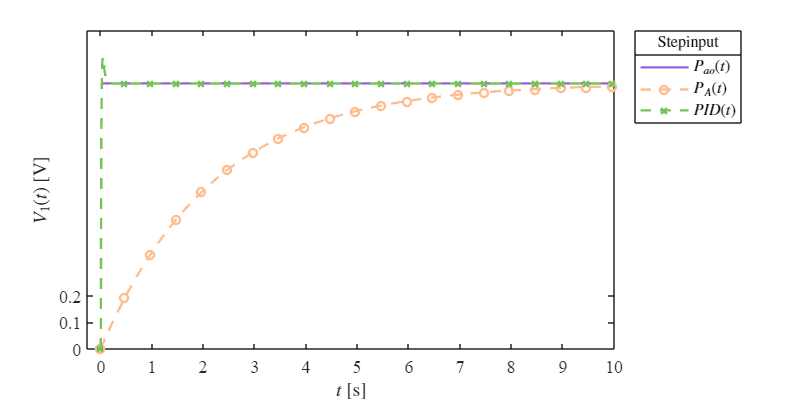

set_param('Sistemas/S1','sw','1')
set_param('Sistemas/Pao(t)','sw','1')
x1 = sim('Sistemas',parameters);
plotsignals(x1.t,x1.Pao,x1.PA,x1.PID,'Step')

## Respuesta al impulso

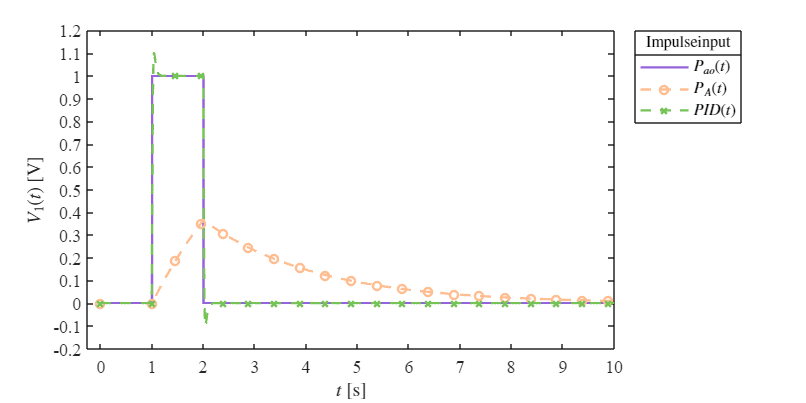

set_param('Sistemas/S1','sw','0')
set_param('Sistemas/Pao(t)','sw','1')
x2 = sim('Sistemas',parameters);
plotsignals(x2.t,x2.Pao,x2.PA,x2.PID,'Impulse')

## Respuesta a la rampa

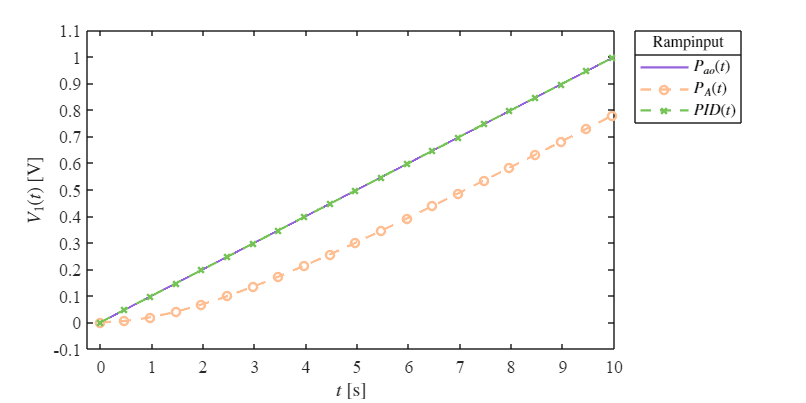

set_param('Sistemas/S2','sw','1')
set_param('Sistemas/Pao(t)','sw','0')
x3 = sim('Sistemas',parameters);
plotsignals(x3.t,x3.Pao,x3.PA,x3.PID,'Ramp')

## Respuesta a la función sinusoidal

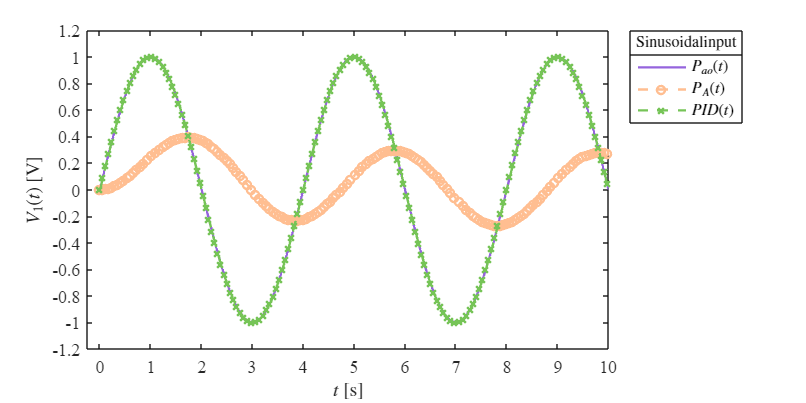

set_param('Sistemas/S2','sw','0')
set_param('Sistemas/Pao(t)','sw','0')
x4 = sim('Sistemas',parameters);
plotsignals(x4.t,x4.Pao,x4.PA,x4.PID,'Sinusoidal')

## Función: Respuestas de la simulación

function plotsignals(t,Pao,PA,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [149,100,221]/255;
    clr2 = [255,190,145]/255;
    clr3 = [118,196,87]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot(t,Pao,'-',t,PA,'--o',t,PID,'--x','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));

    L = legend('$P_{ao}(t)$','$P_A(t)$','$PID(t)$');
    set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
    title(L,[signal, 'input'])

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_1(t)$ [V]','interpreter','latex')

    xlim([-0.25 10]); xticks(0:1:10)

    if signal == "Step"
        ylim([0 1.2]); yticks(0:0.1:0.2)
    elseif signal == "Impulse"
        ylim([-0.2 1.2]); yticks(-0.2:0.1:1.2)
    elseif signal == "Ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    elseif signal == "Sinusoidal"
        ylim([-1.2 1.2]); yticks(-1.2:0.2:1.2)
    end

    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end